# ** GRN Project 2**

Five gene regulatory network motifs are simulated in the code `GRNs_for_HW2.m`. These are:

- Direct negative feedback

- Indirect negative feedback

- Double negative feedback

- Incoherent feed-forward

- Repressilator

For most gene regulatory motifs, as an activating input is increased, the steady-state amount of protein increases gradually. The *biological function* of "ultrasensitivity" or "switch-like response" is a phenomena where the steady-state amount of protein increases slowly, then suddenly, then slowly again. 

# HW2 

Find at least one of the 5 network motifs listed above that produces a switch-like response. Plot the amount of protein as a function of input concentration, showing the switch-like graph.

%% 5.0 ----- DOUBLE NEGATIVE FEEDBACK -----

noisiness = 0;
noisiness2 = 0;

figure(); clf; 

numRuns = 1000;
storage_A = zeros(1,numRuns);
storage_B = zeros(1,numRuns);

iter = 1

iter = 1

paramsweep = linspace(0,5,100)

paramsweep =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


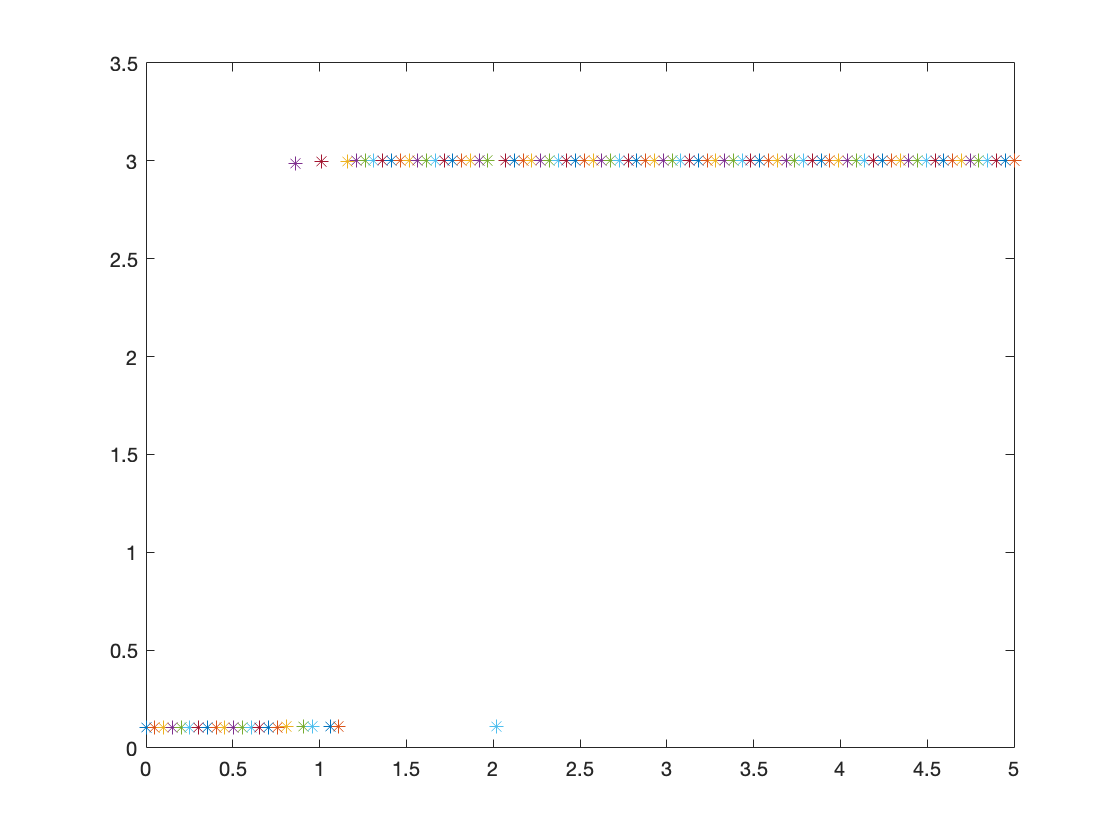

          
for p = paramsweep
                    
    delta_ma = 1*(1+noisiness*rand());
    gamma_pa = 1*(1+noisiness*rand());
    delta_pa = 1*(1+noisiness*rand());
    
    delta_mb = 1*(1+noisiness*randn());
    gamma_pb = 1*(1+noisiness*rand());
    delta_pb = 1*(1+noisiness*rand());
    
    Kba = 1*(1+noisiness2*randn()).*(p); % Strength (IC50^-1) of inhibition of A by B
    Kaa = 0;
    gamma_ma =@(pb) 3./(1+abs(Kba*pb).^3);
    
    Kab = 1*(1+noisiness2*randn()); % Strength (IC50) of inhibition of B by A
    Kbb = 0;
    
    gamma_mb =@(pa) 3./(1+abs(Kab*pa).^3);

    dmadt =@(ma,pa,mb,pb,t) +gamma_ma(pb) - delta_ma*ma;
    dpadt =@(ma,pa,mb,pb,t) +gamma_pa*ma - delta_pa*pa;
    
    dmbdt =@(ma,pa,mb,pb,t) +gamma_mb(pa) - delta_mb*mb;
    dpbdt =@(ma,pa,mb,pb,t) +gamma_pb*mb - delta_pb*pb;

    dxdt = @(t,x)[dmadt(x(1),x(2),x(3),x(4),t);
                  dpadt(x(1),x(2),x(3),x(4),t);
                  dmbdt(x(1),x(2),x(3),x(4),t);
                  dpbdt(x(1),x(2),x(3),x(4),t)];
    
    
    
    initialCondition = 2*rand(4,1);
    
    [T, X] = ode45(dxdt, [0.0,1000], initialCondition);
    plot(p,X(end),'*')
    hold on
    iter = iter + 1;
end
hold off